# Stock Data - Distribution Fitting

In this exercise, you will perform four distribution fits to stock returns data. By overlaying the probability density functions (PDFs) on the histogram of the returns, you can visually assess which distribution fits the data the best.

## 1.

Load data from `stockData_allCapSizes.mat`.

load stockData_allCapSizes.mat

## 2.

Extract the stock prices for Magnum Hunter Resources Corporation (ticker: MHR). Calculate the returns for this stock using the following:

`MHRret``= diff(log(MHR))`

MHR = stockPrices.MHR;

% Calculate the returns
MHRret = diff(log(MHR))

MHRret =          0
   -0.0328
    0.0328
   -0.0245
    0.0082
   -0.0165
   -0.0426
         0
   -0.1298
    0.0099


## 3.

Perform a distribution fit to the MHR returns using Normal, Logistic, and T-Location Scale distributions. Plot the PDF for each fit on top of a histogram of the MHR returns.

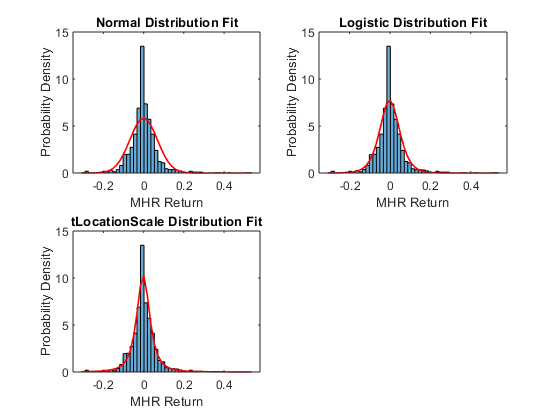

xbins = linspace(min(MHRret), max(MHRret), 50);

% Create a cell array of distribution names and loop though them to create
% the different fits:
dists = {'Normal', 'Logistic', 'tLocationScale'};
retFits = cell(size(dists));
figure
for k = 1:numel(dists)
    retFits{k} = fitdist(MHRret, dists{k});
    fitPDF = pdf(retFits{k}, xbins);
    subplot(2,2,k)
    histogram(MHRret, xbins, 'Normalization', 'pdf')
    hold on
    plot(xbins, fitPDF, 'r', 'LineWidth', 1.2)
    hold off
    title([dists{k}, ' Distribution Fit'])
    xlabel('MHR Return')
    ylabel('Probability Density')
end

## 4.

Perform a nonparametric distribution fit using a kernel smoothing density function. Create a histogram and plot the PDF for the non-parametric distribution fit.

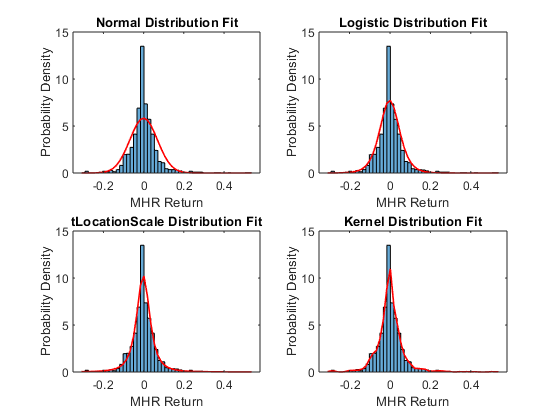

retFits{4} = fitdist(MHRret, 'Kernel');
kernPDF = pdf(retFits{4}, xbins);
subplot(2,2,4)
histogram(MHRret, xbins, 'Normalization', 'pdf')
hold on
plot(xbins, kernPDF, 'r', 'LineWidth', 1.2)
hold off
title('Kernel Distribution Fit')
xlabel('MHR Return')
ylabel('Probability Density')